%{
ES115 Engineering Computer Applications
Module 2 Project: Bridge Deflection Model Comparison

Author: Zulaikha Khan  
Instructor: Lynroy Grant  
Date: April 2026  

Purpose:
This project models and compares the deflection of a bridge using quadratic
equations. A baseline model is created, and then two additional models are
developed by changing specific parameters. The goal is to see how changing
the coefficient "a" affects the curvature of the beam and how changing "c"
affects the vertical position. The models are compared graphically and by
finding their maximum deflection values.

Inputs (Knowns):
- Position along the beam (x) from 0 to 10 meters
- Quadratic model form: d(x) = ax^2 + bx + c
- Model 1 (baseline): a = -0.5, b = 4, c = 2
- Model 2: a = -0.8 (steeper curve), b and c unchanged
- Model 3: c = 5 (vertical shift), a and b unchanged

Outputs (Unknowns):
- Deflection values for each model
- Graph comparing all three models
- Maximum deflection value for each model
- Position along the beam where maximum deflection occurs

Engineering Workflow and Algorithms:
- Define position values along the beam
- Create baseline quadratic model
- Modify coefficient "a" to create Model 2
- Modify constant "c" to create Model 3
- Plot all models on the same graph for comparison
- Use MATLAB functions to find maximum deflection values
- Display results clearly for each model

MATLAB Tools / Functions Used:
- plot() for graphing multiple models
- max() to find maximum deflection values
- indexing to determine corresponding x positions
- fprintf() for formatted output
- element-wise operations (.^) for quadratic calculations

Reflection After Completing the Project:
- I learned how changing parameters in a quadratic equation affects the
  shape and position of the graph, especially how "a" controls curvature
  and "c" shifts the graph vertically.
- If I were to improve this project, I would include more models or vary
  additional parameters like "b" to see how the vertex shifts horizontally.
- Difficulty Rating: 4/10 — this project was mostly straightforward, but
  understanding how each parameter affects the graph was important.
%}



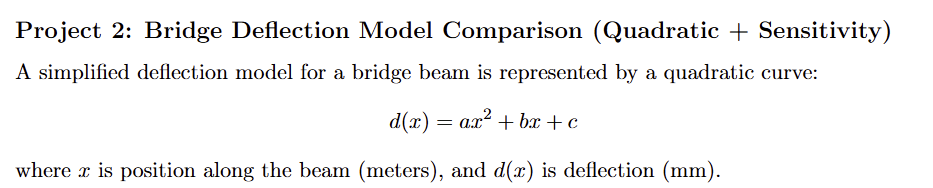

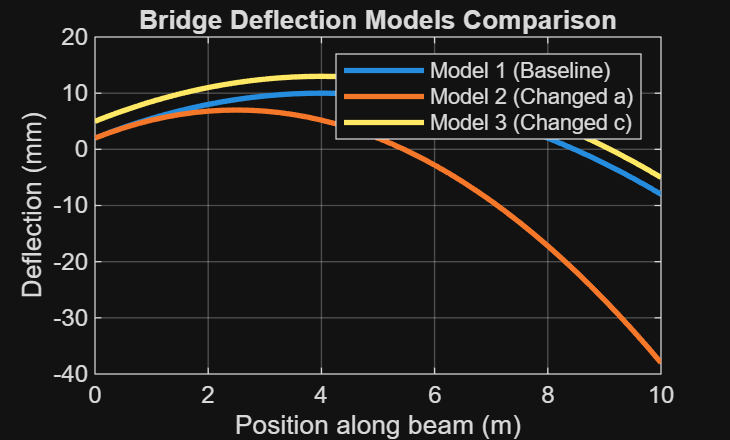

 
clear; clc; close all; 
 
% Define x values (position along beam) 
x = 0:0.25:10; 
 
% ---------------------------- 
% Model 1 (Baseline) 
a1 = -0.5; 
b1 = 4; 
c1 = 2; 
 
d1 = a1*x.^2 + b1*x + c1; 
 
% ---------------------------- 
% Model 2 (change a only) 
a2 = -0.8; % steeper curve 
b2 = b1; 
c2 = c1; 
 
d2 = a2*x.^2 + b2*x + c2; 
 
% ---------------------------- 
% Model 3 (change c only) 
a3 = a1; 
b3 = b1; 
c3 = 5; % vertical shift 
 
d3 = a3*x.^2 + b3*x + c3; 
 
% ---------------------------- 
% Plot all models 
figure; 
plot(x, d1, 'LineWidth', 2); hold on; 
plot(x, d2, 'LineWidth', 2); 
plot(x, d3, 'LineWidth', 2); 
 
title('Bridge Deflection Models Comparison'); 
xlabel('Position along beam (m)'); 
ylabel('Deflection (mm)'); 
legend('Model 1 (Baseline)', 'Model 2 (Changed a)', 'Model 3 (Changed c)'); 
grid on; 

 
% ---------------------------- 
% Find maximum deflection for each model 
 
[max1, idx1] = max(d1); 
x1 = x(idx1); 
 
[max2, idx2] = max(d2); 
x2 = x(idx2); 
 
[max3, idx3] = max(d3); 
x3 = x(idx3); 
 
% Display results 
fprintf('Model 1 max deflection: %.2f mm at x = %.2f m\n', max1, x1); 

Model 1 max deflection: 10.00 mm at x = 4.00 m


fprintf('Model 2 max deflection: %.2f mm at x = %.2f m\n', max2, x2); 

Model 2 max deflection: 7.00 mm at x = 2.50 m


fprintf('Model 3 max deflection: %.2f mm at x = %.2f m\n', max3, x3); 

Model 3 max deflection: 13.00 mm at x = 4.00 m
